clear;
close all;
clc;

% The root directory of the dataset
root_dir = fullfile("p_dataset_26/");

% Load the dataset 
dataset = imageDatastore(root_dir, "IncludeSubfolders", true, "LabelSource", "foldernames");

% Counting the number of images for every label and displaying it on a table
table = countEachLabel(dataset);
disp(table);

    Label    Count
    _____    _____

      0       254 
      4       254 
      7       254 
      8       254 
      A       254 
      D       254 
      H       254 



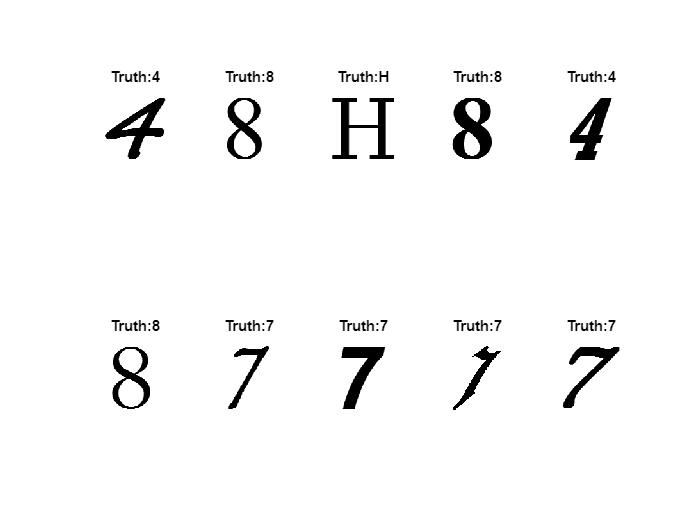


% Check if the dataset has been loaded properly
% Randomize 10 numbers and generate total number of images in the dataset 
random__num = randperm(sum(table.Count), 10);
figure;
for i = 1:10 
    subplot(2, 5, i);
    imshow(dataset.Files{random__num(i)}); % Divide into 2x5 grid of subplot
    title(['Truth:' char(dataset.Labels(random__num(i)))]);
end


% Dividing the dataset into training set and test (validation) set 
% Training set: test set = 0.75 : 0.25
[trainset, testset] = splitEachLabel(dataset, 0.75, "randomized");

% Initializing parameters for feature extraction from training set
train_num = numel(trainset.Files);
test_num = numel(testset.Files);

% Training the dataset
% The actual extraction of Sobel features from each image in the training set
train_feat = [];
train_labels = trainset.Labels;
for i = 1:train_num
    img = readimage(trainset, i);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    edgeFeature = edge(img, 'Sobel');
    train_feat = [train_feat; edgeFeature(:)'];
end

% Train using binary SVM classifiers in one vs all scheme 
SVM = fitcecoc(train_feat, train_labels);

% Obtaining the accuracy of the SVM
% Extracting Sobel features from the test images
test_feat = [];
test_label = testset.Labels;
for j = 1:test_num
    img = readimage(testset, j);
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    edgeFeature = edge(img, 'Sobel');
    test_feat = [test_feat; edgeFeature(:)'];
end

% Predicting labels using SVM classifiers
predicted_label = predict(SVM, test_feat);

% Calculate accuracy
accuracy = sum(predicted_label == test_label) / numel(test_label);
disp(accuracy);

    0.8844



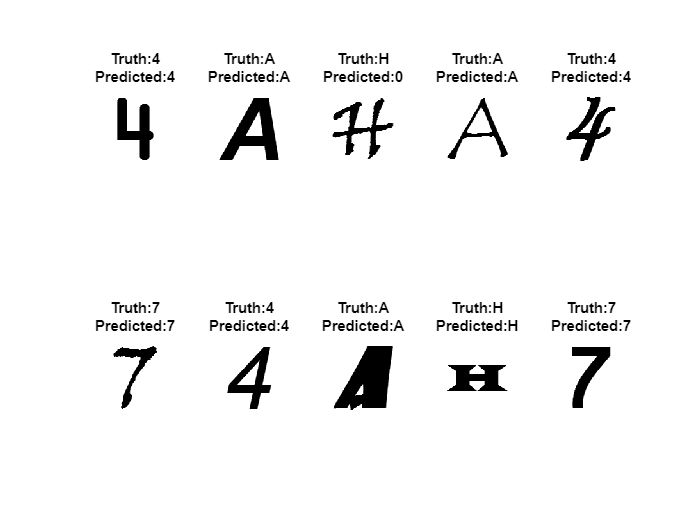


% Predicted Labels vs Actual Labels
random_num = randperm(numel(predicted_label), 10);
figure;
for i = 1:10
    subplot(2, 5, i);
    imshow(testset.Files{random_num(i)});
    title({['Truth:' char(test_label(random_num(i)))], ['Predicted:' char(predicted_label(random_num(i)))]});
end

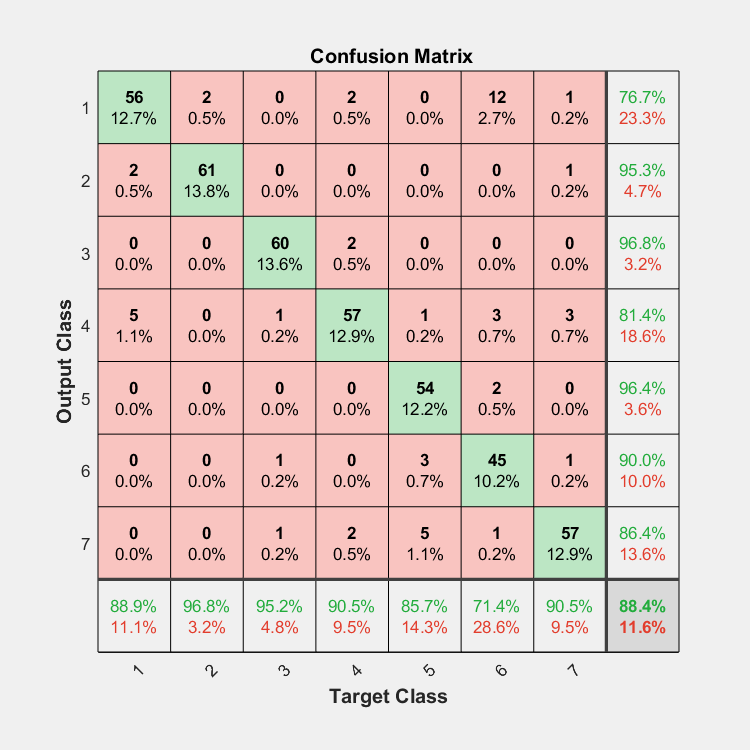


% Confusion Matrix for evaluating performance
figure;
plotconfusion(ind2vec(double(grp2idx(test_label))'), ind2vec(double(grp2idx(predicted_label))'));

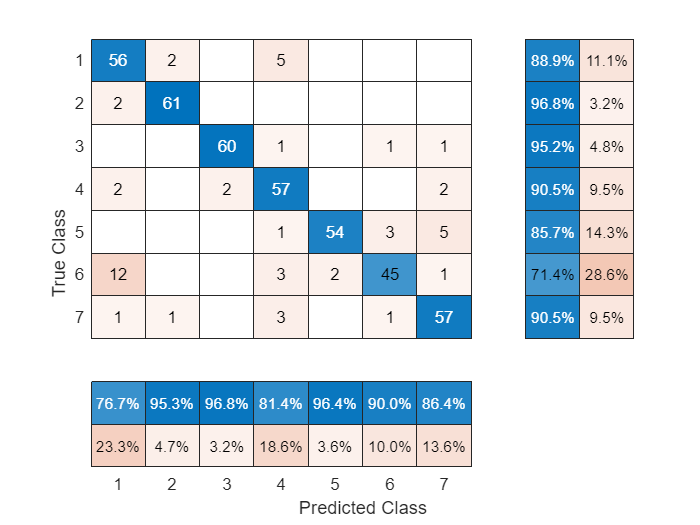


% Confusion chart for evaluating performance
figure;
confMat = confusionmat(test_label, predicted_label);
chart = confusionchart(confMat, 'RowSummary', 'row-normalized', 'ColumnSummary', 'column-normalized');


% Saving SVM
% SVM_Sobol = SVM;
% save SVM_Sobol
